# Example for using the `reduce_data_points` function.

Copyright © 2022 Tamas Kis

## Example #1: Univariate data set.

First, we "generate" a data set by evaluating the function


$$y=x+\sin \left(x\right)$$


at every point in $\mathbf{x}$, where $\mathbf{x}$ is defined as


$$\mathbf{x}=\left\lbrack \begin{array}{ccccc}
0 & 0\ldotp 01 & 0\ldotp 02 & \cdots  & 10
\end{array}\right\rbrack$$


In MATLAB,

x = 0:0.01:10;
y = x+sin(x);

Now, we have two vectors, $\mathbf{x}$ and $\mathbf{y}$, which form a data set; the elements of $\mathbf{x}$ store the values of the independent variable, while the elements of $\mathbf{y}$ stores the values of the dependent variable. To shrink the data set so that there are only five data points $\left(x_i ,y_i \right)$,

[x_new,y_new] = reduce_data_points(x,y,5);

Plotting the old data set (dotted line; individual points not plotted) together with the new data set (circles, with solid lines connecting them),

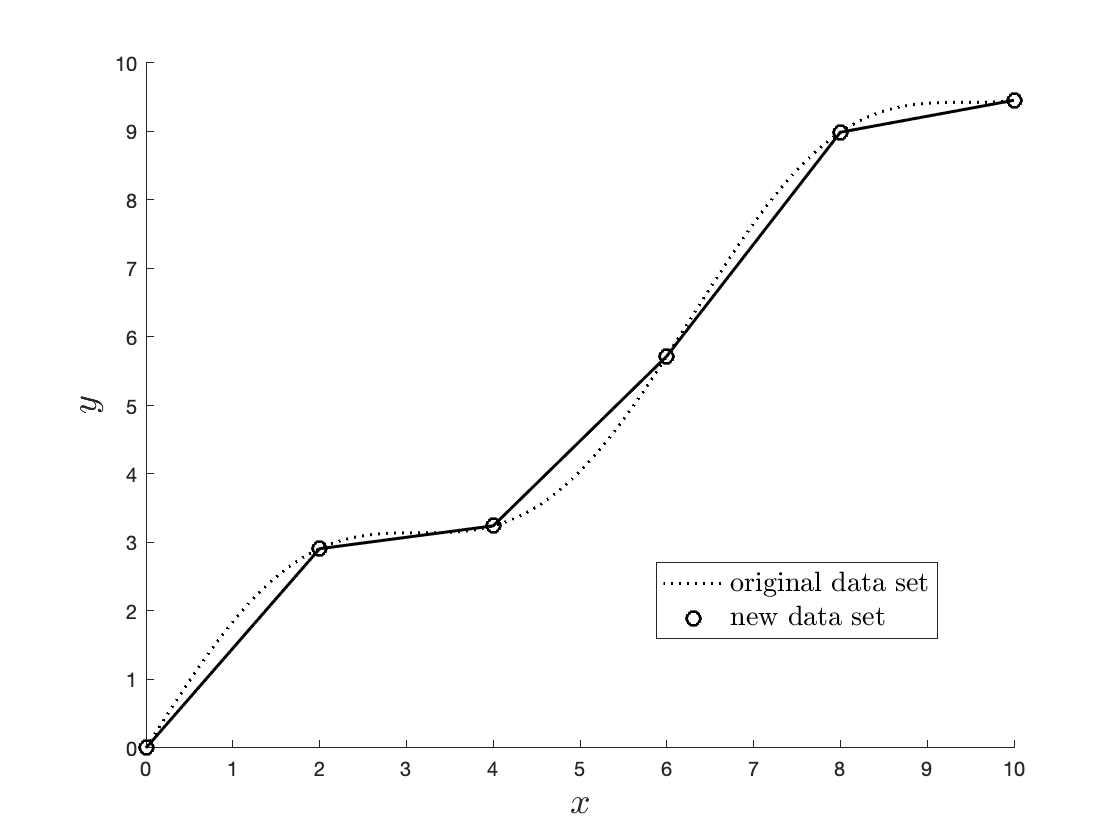

figure;
hold on;
plot(x,y,'k:','LineWidth',1.5);
plot(x_new,y_new,'Color','k','LineWidth',1.5,'HandleVisibility',...
    'off');
plot(x_new,y_new,'o','LineWidth',1.5,'MarkerSize',7,'Color','k');
hold off;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('original data set','new data set','Interpreter','latex',...
    'FontSize',14,'Location','best');

Note that the new data set has 6 data points, whereas we requested only 5. However, there is no direct way to resolve this; we do not wish to remove the endpoints from the data set, we want to select the points as uniformly as possible, and we can only select integer indices. In most cases, the function will return $N\pm 1$ data points, where $N$ is the requested number of data points.

## Example #2: Data set with three variables.

First, we "generate" a data set by evaluating the functions


$$y=x+\sin \left(x\right)$$



$$z=x-\cos \left(x\right)$$


at every point in $\mathbf{x}$, where $\mathbf{x}$ is defined as


$$\mathbf{x}=\left\lbrack \begin{array}{ccccc}
0 & 0\ldotp 01 & 0\ldotp 02 & \cdots  & 10
\end{array}\right\rbrack$$


In MATLAB,

x = 0:0.01:10;
y = x+sin(x);
z = x-cos(x);

Now, we have three vectors, $\mathbf{x}$, $\mathbf{y}$, and $\mathbf{z}$, which form a data set; the elements of $\mathbf{x}$ store the values of the independent variable, while the elements of $\mathbf{y}$ and $\mathbf{z}$ store the values of the two dependent variables. To shrink the data set so that there are only 11 data points $\left(x_i ,y_i ,z_i \right)$,

[x_new,y_new,z_new] = reduce_data_points(x,y,z,11);

In this case, we get exactly 11 data points:

length(x_new)

ans = 11